    clc
    clear
    close all
    
    
    % QUESTO E QUELLO GIUSTO!!! 
    
    main_folder='path_folder';
    data_folder_general=fullfile(main_folder,'MRI_nii_folder');
    %in data folder dove ci sono i file .nii
    data_folder='path_to_T1W_nii';
    cd(data_folder)
    
    batch_folder=fullfile(main_folder,'path_where_the_batches_are');
    
    cd 'path_to\spm12'
    spm_location=which('spm');
    [spm_folder,~,~,~]=spm_fileparts(spm_location);

    %Location of the template tissue probabilistic maps
    tpm_path=fullfile(spm_folder,'tpm','TPM.nii') % tpm_path?
    
    % folder that might be defined for every subgroup of subjects that are
    % processed
        logfile_folder=fullfile(data_folder,'logfiles');
        
        mkdir(logfile_folder)
        
%T1 MRI images for each subject
% select original images from folder (all files with .nii extension).
% Other filters can be added

imgs=spm_select('FPList',data_folder,'nii')

%Check the images that have been done
%label_folder=fullfile(data_folder, 'label')
report_folder=fullfile(data_folder, 'report')
%imgs_done_label=spm_select('FPList',label_folder,'mat')
imgs_done_report=spm_select('FPList',report_folder,'pdf')
%seg_folder=fullfile(data_folder, 'mri')
%imgs_done_segmentation=spm_select('FPList',seg_folder,'mwp1')
imgs_done = extractBetween(cellstr(imgs_done_report),"path_to_saving_folder\report\catreport_",".pdf");
idx_undone=~contains(cellstr(imgs),cellstr(imgs_done));
imgs=imgs(idx_undone,:);
n_subj=size(imgs,1) % n images to do 

## check image orientation : only if necessary

% if images have never been inspected
for s=1:4%n_subj
    subj_image=imgs(s,:);
    spm_image('Display',subj_image);
end

If spmjob error: run everything until here -> write spm in command window just to open it -> select section cat12segmentation-> clear all output -> run section

## cat12 segmentation 

load(fullfile(batch_folder,'cat12_segment_ROI_analyses_template.mat')); % batch with default parameters
job_name='cat12_segment_all_subjects'; % name for batch file with the selected subjects, which will be saved in the logfile folder


path_template='path_to\spm12\toolbox\cat12\templates_volumes\Template_0_IXI555_MNI152_GS.nii'
% change tpm pathway if needed

%do le T1 weighted image? TPM= tissue probability map paths
matlabbatch{1}.spm.tools.cat.estwrite.opts.tpm{1}=tpm_path;

matlabbatch{1}.spm.tools.cat.estwrite.data={};

%riempio il campo data
% add all subject images to segment
for s=1:n_subj
    subj_image=imgs(s,:);
    matlabbatch{1}.spm.tools.cat.estwrite.data{s,1}=[subj_image,',1'];
end

save(fullfile(logfile_folder,job_name));
matlabbatch{1}.spm.tools.cat.estwrite.data_wmh = {''};
matlabbatch{1}.spm.tools.cat.estwrite.useprior = '';
matlabbatch{1}.spm.tools.cat.estwrite.nproc = 8; % Blocking call to CAT12
matlabbatch{1}.spm.tools.cat.estwrite.extopts.registration.shooting.shootingtpm={path_template};
%così funziona
output=spm_jobman('run',matlabbatch);
%OUTPUT: normalized bias-corrected volume! per me T1 immagino


## NB. da runnare senza fare display axial slice di tutte

 pre_proc_data_folder=fullfile(data_folder,'mri'); % where pre-processed images are saved
 % select normalized bias corrected volumes
 norm_images=spm_select('FPList',pre_proc_data_folder,'wm')

## display axial slice centered on the origin for all images

2° modulo del Manuale: Display slices


    load(fullfile(batch_folder,'cat12_display_origin_slices.mat')); % batch with default parameters
    job_name='cat12_display_all_subjects'; % name for batch file with the selected subjects, which will be saved in the logfile folder
    
    pre_proc_data_folder=fullfile(data_folder,'mri'); % where pre-processed images are saved
    
    % select normalized bias corrected volumes
    norm_images=spm_select('FPList',pre_proc_data_folder,'wm')

% check on the number of images, which should be the same as the original
if ~isequal(size(norm_images,1),n_subj)
    msgbox('missing some pre-processed images');
end


matlabbatch{1}.spm.tools.cat.tools.showslice.data_vol={};

% add all subject images to visualize
for s=1:n_subj
    subj_image=norm_images(s,:);
    matlabbatch{1}.spm.tools.cat.tools.showslice.data_vol{s,1}=[subj_image,',1'];
end

save(fullfile(logfile_folder,job_name));
spm_jobman('run',matlabbatch);

## intracranial volume computation (TIV computation)

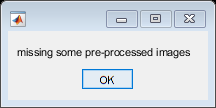

load(fullfile(batch_folder,'cat12_globals.mat')); % batch with default parameters
job_name='cat12_globals_all_subjects';  % name for batch file with the selected subjects, which will be saved in the logfile folder

report_folder=fullfile(data_folder,'report'); % where pre-processed images are saved

% select xml files with segmentation parameters that are saved in the
% report folder
xml_files=spm_select('FPList',report_folder,'xml$'); 

if ~isequal(size(xml_files,1),n_subj)
    msgbox('missing some pre-processed images');
end


matlabbatch{1}.spm.tools.cat.tools.calcvol.data_xml={};

% add all subject images to segment
for s=1:16%n_subj
    print(xml_files(s,:));
    matlabbatch{1}.spm.tools.cat.tools.calcvol.data_xml{s,1}=xml_files(s,:);
end

Error using validateHandleToPrint
No figure to print.

Error in validate (line 17)
pj = validateHandleToPrint(pj); 

Error in print (line 67)
pj = validate( pj );


save(fullfile(logfile_folder,job_name));
output=spm_jobman('run',matlabbatch);

## check GM mwp1 image intensity homogeneity in the sample (to be performed on the entire sample. default parameters, only one group and no confounding effects considered (e.g. age, ITV))

load(fullfile(batch_folder,'cat12_check_homogeneity.mat')); % batch with default parameters
job_name='cat12_qc_final_gm_all_subjects';  % name for batch file with the selected subjects, which will be saved in the logfile folder

% select modulated, normalized GM maps
%2x110 char
gm_images=spm_select('FPList',pre_proc_data_folder,'^mwp1');


if ~isequal(size(gm_images,1),n_subj)
    msgbox('missing some pre-processed images');
end

matlabbatch{1}.spm.tools.cat.tools.check_cov.data_vol{1}={};

% add all subject images to segment
for s=1:n_subj
    matlabbatch{1}.spm.tools.cat.tools.check_cov.data_vol{1}{s,1}=[gm_images(s,:),',1'];
end
%add xlm_files!!
for s=1:n_subj
    matlabbatch{1}.spm.tools.cat.tools.check_cov.data_xml{s,1}=xml_files(s,:);
end

save(fullfile(logfile_folder,job_name));
spm_jobman('run',matlabbatch);

## GM image smoothing --> I have selected FWHM=6 mm, but we can discuss it


load(fullfile(batch_folder,'spatial_smooth_6mm.mat')); % batch with default parameters
job_name='smooth_6mm_gm_all_subjects';  % name for batch file with the selected subjects, which will be saved in the logfile folder

% if you wish to change FWHM
matlabbatch{1}.spm.spatial.smooth.fwhm=[6,6,6];

matlabbatch{1}.spm.spatial.smooth.data={};

% add all subject images to segment
for s=1:n_subj
    matlabbatch{1}.spm.spatial.smooth.data{s,1}=[gm_images(s,:),',1'];
end

save(fullfile(logfile_folder,job_name));
spm_jobman('run',matlabbatch);

Item 'Images to smooth', field 'val': Number of matching files (0) less than required (1).


Error using spm_jobman>fill_run_job (line 472)
No executable modules, but still unresolved dependencies or incomplete module inputs.

Error in spm_jobman (line 247)
        sts = fill_run_job('run', cjob, varargin{3:end});

## check WM mwp2 image intensity homogeneity in the sample (to be performed on the entire sample. default parameters, only one group and no confounding effects considered (e.g. age, ITV))

load(fullfile(batch_folder,'cat12_check_homogeneity.mat')); % batch with default parameters
job_name='cat12_qc_final_wm_all_subjects';  % name for batch file with the selected subjects, which will be saved in the logfile folder

% select modulated, normalized GM maps
wm_images=spm_select('FPList',pre_proc_data_folder,'^mwp2'); 

if isequal(size(wm_images,1),n_subj)==0
    msgbox('missing some pre-processed images');
end

matlabbatch{1}.spm.tools.cat.tools.check_cov.data_vol{1}={};

% add all subject images to segment
for s=1:n_subj
    matlabbatch{1}.spm.tools.cat.tools.check_cov.data_vol{1}{s,1}=[wm_images(s,:),',1'];
end

%add xlm_files!!
for s=1:n_subj
    matlabbatch{1}.spm.tools.cat.tools.check_cov.data_xml{s,1}=xml_files(s,:);
end

save(fullfile(logfile_folder,job_name));
spm_jobman('run',matlabbatch);

## WM mpw2 image smoothing --> I have selected FWHM=6 mm, but we can discuss it

load(fullfile(batch_folder,'spatial_smooth_6mm.mat')); % batch with default parameters
job_name='smooth_6mm_wm_all_subjects';  % name for batch file with the selected subjects, which will be saved in the logfile folder

% if you wish to change FWHM
matlabbatch{1}.spm.spatial.smooth.fwhm=[6,6,6];

matlabbatch{1}.spm.spatial.smooth.data={};

% add all subject images to segment     
for s=1:n_subj
    matlabbatch{1}.spm.spatial.smooth.data{s,1}=[wm_images(s,:),',1'];
end

save(fullfile(logfile_folder,job_name));
spm_jobman('run',matlabbatch);